ans =   Simulink.SimulationOutput:

                   tout: [1188x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


AccelerationData =          0         0         0         0         0         0         0
    0.0100         0         0   15.5571         0         0         0
    0.0200         0         0    9.8471         0         0         0
    0.0300         0         0    4.7789         0         0         0
    0.0400         0         0    5.4976         0         0         0
    0.0500         0         0    6.2164         0         0         0
    0.0600         0         0    6.9354         0         0         0
    0.0700         0         0    7.6546         0         0         0
    0.0800         0         0    8.3739         0         0         0
    0.0900         0         0    9.0934         0         0         0


accelReadings =    -0.0661         0   10.4236
   -0.2340         0   26.7132
   -0.5053         0   18.7553
    0.5836         0   14.2455
   -0.0909         0   15.7293
   -1.2622         0   15.3556
   -1.0339         0   16.2050
    0.4229         0   16.8258
    1.3478         0   17.4911
    0.6693         0   18.6121


gyroReadings =          0   -0.0053         0
         0   -0.0112         0
         0    0.0051         0
         0   -0.0048         0
         0   -0.0062         0
         0   -0.0021         0
         0    0.0156         0
         0   -0.0057         0
         0   -0.0027         0
         0    0.0048         0


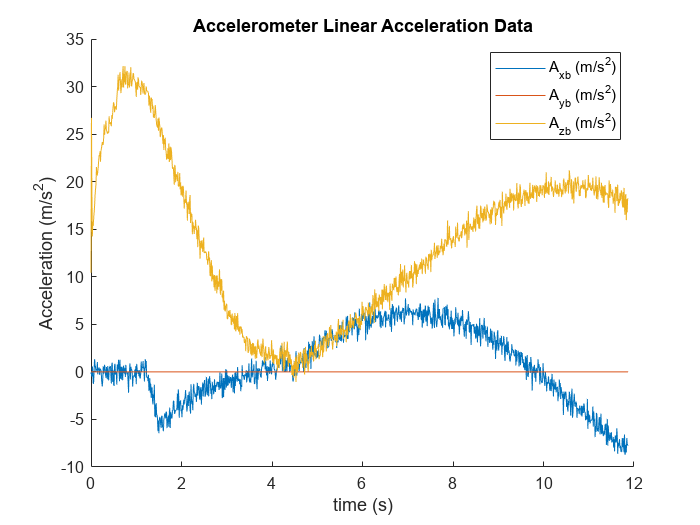

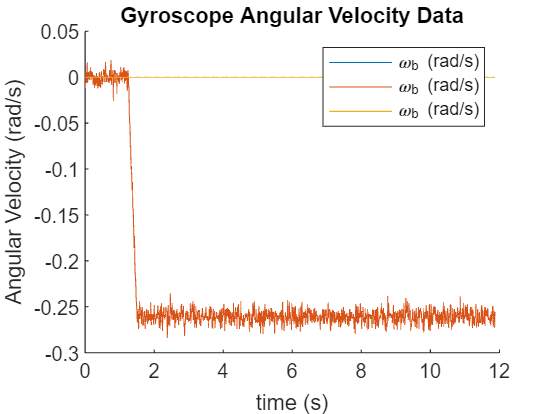

clc; clear; close all; format compact;

Create_IMU_noisy_data;

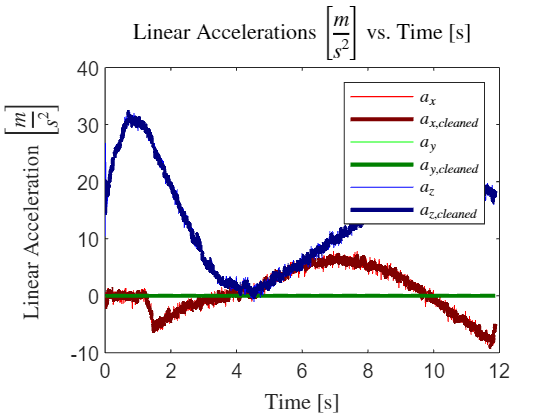

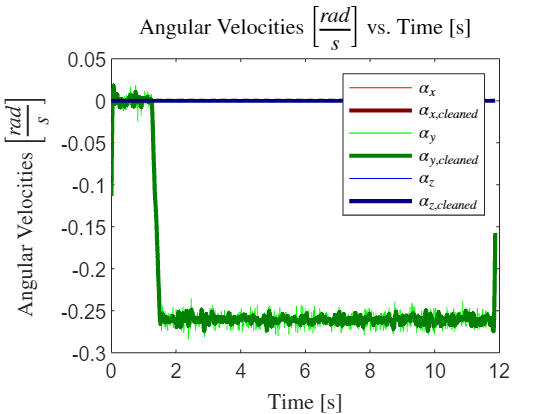


Data_Processing;

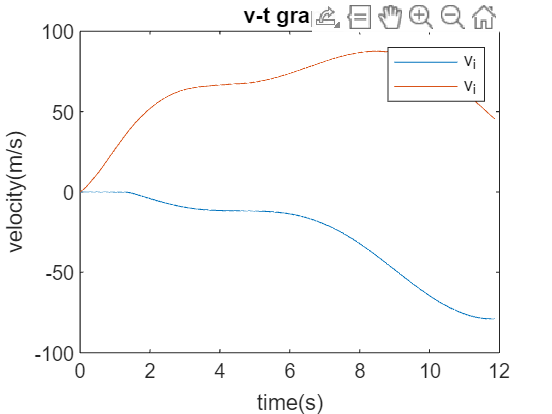



CleanedData = struct2array(load('Acceleration Data.mat'));

% time  ax  ay  az  omega_x  omega_y  omega_z


t = CleanedData(:,1); %s
ax_b = CleanedData(:,2); %m/s^2
ay_b = CleanedData(:,3);
az_b = CleanedData(:,4);
omega_x_b = CleanedData(:,5); %rad/s
omega_y_b = CleanedData(:,6); %rad/s
omega_z_b = CleanedData(:,7);

theta_y = cumtrapz(t,omega_y_b) + pi/2; %rad


A_i = zeros(3,length(t));
for ctr = 1:length(t)
    R=[sin(theta_y(ctr))     0    cos(theta_y(ctr));
         0              1           0;
       -cos(theta_y(ctr))        0      sin(theta_y(ctr))]; %interial to body
    A_b = [ax_b(ctr);
           ay_b(ctr);
           az_b(ctr);];
    A_i(:,ctr) = R'*A_b;
end

a_x_i = A_i(1,:); %m/s^2
a_y_i = A_i(2,:);
a_z_i = A_i(3,:);



v_x_i = cumtrapz(t,a_x_i);
v_z_i = cumtrapz(t,a_z_i);

x_i = cumtrapz(t,v_x_i);
z_i = cumtrapz(t,v_z_i);


figure
plot(t,v_x_i,t,v_z_i)
xlabel('time(s)');ylabel('velocity(m/s)');title('v-t graph')
legend('v_x_,_i','v_z_,_i')

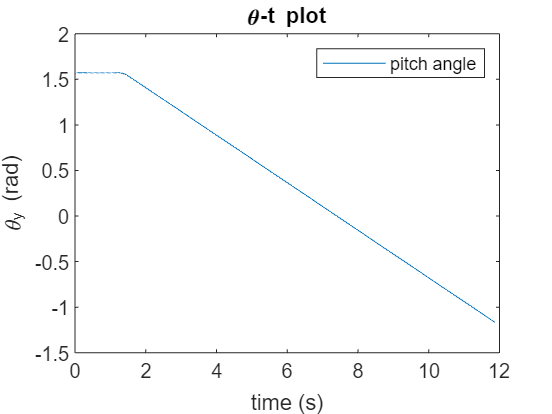

figure
plot(t,theta_y); xlabel('time (s)'); ylabel('\theta_y (rad)'); title('\theta-t plot')
legend('pitch angle')

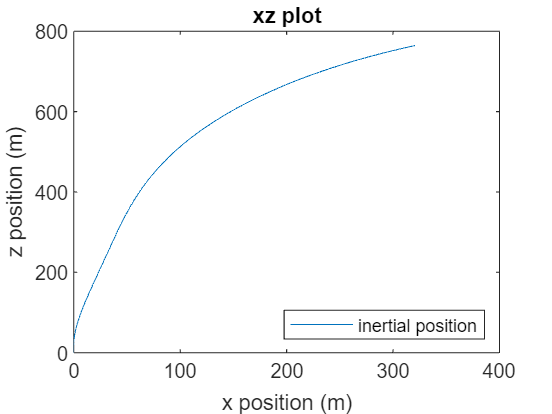

figure
plot(-x_i,z_i); xlabel('x position (m)'); ylabel('z position (m)'); title('xz plot') %x is negative for some reason
    legend('inertial position','location','southeast')

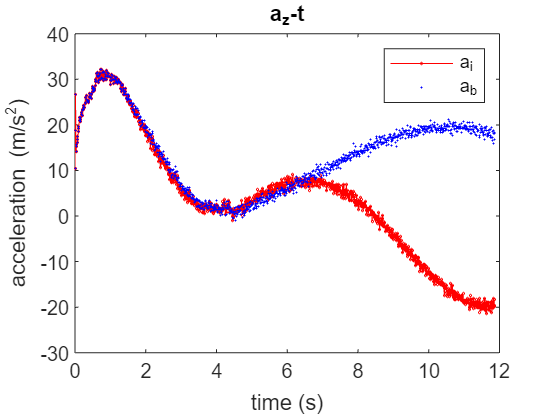

figure;
plot(t,a_z_i,'r-d',t,az_b,'b.',MarkerSize=1); xlabel('time (s)'); ylabel('acceleration (m/s^2)'); title('a_z-t')
legend('a_z_,_i','a_z_,_b')

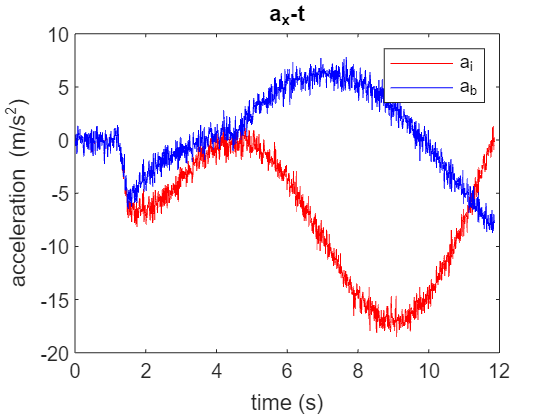

figure
plot(t,a_x_i,'r',t,ax_b,'b'); xlabel('time (s)'); ylabel('acceleration (m/s^2)'); title('a_x-t')
legend('a_x_,_i','a_x_,_b')